%% 初始化與全域參數設定 (Step 0)
clc; clear; close all force;

fprintf('  馬達 AI 系統\n');

  馬達 AI 系統


fprintf('====================================================\n');


% --- 馬達名目物理參數設定 ---
p       = 4;            % 極對數
Rs      = 0.033947;     % 定子電阻
Ld      = 0.000525;     % d軸電感 (常數備用)
Lq      = 0.001126;     % q軸電感 (常數備用)
Flux    = 0.143140;     % 永磁體磁鏈
Imax    = 405;          % 變頻器極限電流
Vdc     = 664;          % 依照實驗真實條件，精準對齊 664V
V_limit = (Vdc / sqrt(3)) * 0.95; % 預留 5% 裕度的電壓極限

% --- 建立動態 Ld/Lq 查表函數 ---
id_axis = linspace(-350, 0, 31);
iq_axis = linspace(0, 350, 31);
[ID_grid, IQ_grid] = ndgrid(id_axis, iq_axis);

% 載入實驗測得的動態電感表，若無則退回固定電感
try
    % 指定同一個 Excel 檔案名稱 (請確認檔名是否正確)
    filename = 'Ldq_LUT.xlsx'; 

    % 分別讀取同一個檔案中的 'Ld_LUT' 與 'Lq_LUT' 兩個分頁
    Ld_mat = flipud(readmatrix(filename, 'Sheet', 'Ld_LUT')');
    Lq_mat = flipud(readmatrix(filename, 'Sheet', 'Lq_LUT')');

    % 建立插值物件
    Ld_interp_obj = griddedInterpolant(ID_grid, IQ_grid, Ld_mat, 'linear', 'nearest');
    Lq_interp_obj = griddedInterpolant(ID_grid, IQ_grid, Lq_mat, 'linear', 'nearest');

    % 存入馬達結構體
    motor.Ld_interp = @(id, iq) Ld_interp_obj(id, iq);
    motor.Lq_interp = @(id, iq) Lq_interp_obj(id, iq);
    
    fprintf('成功從單一檔案載入動態 Ld / Lq LUT。\n');
catch ME
    motor.Ld_interp = @(id, iq) Ld;
    motor.Lq_interp = @(id, iq) Lq;
    fprintf('載入 Ld/Lq LUT 失敗，自動套用固定電感值。錯誤原因：%s\n', ME.message);
end

成功從單一檔案載入動態 Ld / Lq LUT。



motor.p       = p;
motor.Rs      = Rs;
motor.Ld      = Ld;
motor.Lq      = Lq;
motor.Flux    = Flux;
motor.Imax    = Imax;
motor.V_limit = V_limit;

% --- 配置檔案路徑與欄位對應 (全域設定) ---
cfg.files.trainData = '20250520_500rpm_13000rpm_effMap_Report.csv';
cfg.mapping.spd     = 'SPEED';
cfg.mapping.trq     = 'TORQUE';
cfg.mapping.id      = 'daxisCurrCmd';
cfg.mapping.iq      = 'qaxisCurrCmd';

%% Step 1: 數據讀取、預處理
fprintf('\n▶ [1/6] Step 1: 數據讀取與處理...\n');


▶ [1/6] Step 1: 數據讀取與處理...



data  = readtable(cfg.files.trainData);
X_raw = [data.(cfg.mapping.trq), data.(cfg.mapping.spd)];
Y_raw = [data.(cfg.mapping.id), data.(cfg.mapping.iq)];

I_mag_raw = sqrt(Y_raw(:,1).^2 + Y_raw(:,2).^2);

transient_mask = false(size(X_raw, 1), 1);
valid = ~any(isnan(X_raw), 2) & ~any(isnan(Y_raw), 2) & X_raw(:,1) >= 0 & X_raw(:,2) >= 0 & ~transient_mask;

I_max_data = ceil(prctile(I_mag_raw(valid), 99.5) / 10) * 10;
if I_max_data < Imax && I_max_data > 50
    Imax       = I_max_data;
    motor.Imax = Imax;
end
I_plot_limit = Imax + 10;

valid   = valid & (I_mag_raw <= (Imax * 1.1));
X_clean = X_raw(valid, :);
Y_clean = Y_raw(valid, :);

res_T  = 2;
res_S  = 20;
X_grid = [round(X_clean(:,1) / res_T) * res_T, round(X_clean(:,2) / res_S) * res_S];
[X_unique, ~, binIdx] = unique(X_grid, 'rows');
binCounts = accumarray(binIdx, 1);

min_pts           = 1;
valid_bins        = binCounts >= min_pts;
valid_bin_indices = find(valid_bins);

X_clean_dense = X_unique(valid_bins, :);
Y_clean_dense = zeros(length(valid_bin_indices), 2);

for k = 1:length(valid_bin_indices)
    orig_idx   = valid_bin_indices(k);
    pts_in_bin = Y_clean(binIdx == orig_idx, :);

    if size(pts_in_bin, 1) >= 3
        outliers   = isoutlier(pts_in_bin, 'median', 'ThresholdFactor', 2.5);
        good_pts = pts_in_bin(~outliers(:,1) & ~outliers(:,2), :);
        if ~isempty(good_pts)
            Y_clean_dense(k, :) = mean(good_pts, 1);
        else
            Y_clean_dense(k, :) = median(pts_in_bin, 1);
        end
    else
        Y_clean_dense(k, :) = mean(pts_in_bin, 1);
    end
end

X_clean_final = X_clean_dense;
Y_clean_final = Y_clean_dense;

fw_idx = find(X_clean_final(:,2) >= 9000 | Y_clean_final(:,1) <= -150);
if ~isempty(fw_idx)
    X_fw_extra = repmat(X_clean_final(fw_idx, :), 2, 1);
    Y_fw_extra = repmat(Y_clean_final(fw_idx, :), 2, 1);
    X_clean_final = [X_clean_final; X_fw_extra];
    Y_clean_final = [Y_clean_final; Y_fw_extra];
end

Y_theory_final = calculate_theoretical_currents(X_clean_final(:,1), X_clean_final(:,2), motor);

valid_theory = ~any(isnan(Y_theory_final), 2);
X_clean  = X_clean_final(valid_theory, :);
Y_clean  = Y_clean_final(valid_theory, :);
Y_theory = Y_theory_final(valid_theory, :);

[~, sort_idx] = sortrows(X_clean, [2, 1]);
X_clean  = X_clean(sort_idx, :);
Y_clean  = Y_clean(sort_idx, :);
Y_theory = Y_theory(sort_idx, :);

Y_target_direct   = Y_clean;
Y_target_residual = Y_clean - Y_theory(:, 1:2);

fprintf('   - 原始數據: %d 筆 | 處理後乾淨數據: %d 筆\n', size(X_raw,1), size(X_clean, 1));

   - 原始數據: 313 筆 | 處理後乾淨數據: 519 筆


Cleaned_Data_Table = table(X_clean(:,2), X_clean(:,1), Y_clean(:,1), Y_clean(:,2), 'VariableNames', {'Speed_RPM', 'Torque_Nm', 'Id_A', 'Iq_A'});
writetable(Cleaned_Data_Table, 'Cleaned_Motor_Data.csv');

save('processed_bundle.mat', 'X_raw', 'Y_raw', 'X_clean', 'Y_clean', 'Y_target_direct', 'Y_target_residual', 'Y_theory', 'cfg', 'motor', 'I_plot_limit', 'Imax');

%% 原始訓練數據分布分析 (EDA Dashboard)
try
    data = readtable(cfg.files.trainData);
catch
    error('找不到 %s，請確認檔案是否在當前目錄中。', cfg.files.trainData);
end

trq = data.(cfg.mapping.trq); id  = data.(cfg.mapping.id); iq  = data.(cfg.mapping.iq);

Ld_eda = motor.Ld_interp(id, iq);
Lq_eda = motor.Lq_interp(id, iq);
flux_mag = sqrt((motor.Flux + Ld_eda.*id).^2 + (Lq_eda.*iq).^2);

total_pts = length(trq);
fprintf('\n========================================\n');

fprintf('       動力計實驗數據報告 (True Physical Wb)\n');

       動力計實驗數據報告 (True Physical Wb)


fprintf('========================================\n');

fprintf('總資料筆數 : %d 筆\n\n', total_pts);

總資料筆數 : 313 筆




low_flux = sum(flux_mag < 0.08); mid_flux = sum(flux_mag >= 0.08 & flux_mag < 0.13); high_flux = sum(flux_mag >= 0.13);
fprintf('【物理定子磁鏈分布 (真實 Wb)】\n');

【物理定子磁鏈分布 (真實 Wb)】


fprintf(' - 深度弱磁 (< 0.08 Wb)    : %3d 筆 (佔 %.1f%%)\n', low_flux, (low_flux/total_pts)*100);

 - 深度弱磁 (< 0.08 Wb)    :  47 筆 (佔 15.0%)


fprintf(' - 中等弱磁 (0.08~0.13 Wb) : %3d 筆 (佔 %.1f%%)\n', mid_flux, (mid_flux/total_pts)*100);

 - 中等弱磁 (0.08~0.13 Wb) :  44 筆 (佔 14.1%)


fprintf(' - MTPA 區 (>= 0.13 Wb)    : %3d 筆 (佔 %.1f%%)\n\n', high_flux, (high_flux/total_pts)*100);

 - MTPA 區 (>= 0.13 Wb)    : 222 筆 (佔 70.9%)




low_trq  = sum(trq < 100); mid_trq  = sum(trq >= 100 & trq < 200); high_trq = sum(trq >= 200);
fprintf('【扭矩分布】\n');

【扭矩分布】


fprintf(' - 輕載 (< 100 Nm)        : %3d 筆 (佔 %.1f%%)\n', low_trq, (low_trq/total_pts)*100);

 - 輕載 (< 100 Nm)        : 160 筆 (佔 51.1%)


fprintf(' - 中載 (100~200 Nm)      : %3d 筆 (佔 %.1f%%)\n', mid_trq, (mid_trq/total_pts)*100);

 - 中載 (100~200 Nm)      :  96 筆 (佔 30.7%)


fprintf(' - 重載 (>= 200 Nm)       : %3d 筆 (佔 %.1f%%)\n\n', high_trq, (high_trq/total_pts)*100);

 - 重載 (>= 200 Nm)       :  57 筆 (佔 18.2%)




fw_pts = sum(id < -150);
fprintf('【弱磁區分析】\n');

【弱磁區分析】


fprintf(' - 深度弱磁點 (Id < -150A): %3d 筆 (佔 %.1f%%)\n', fw_pts, (fw_pts/total_pts)*100);

 - 深度弱磁點 (Id < -150A):  96 筆 (佔 30.7%)


fprintf('========================================\n');

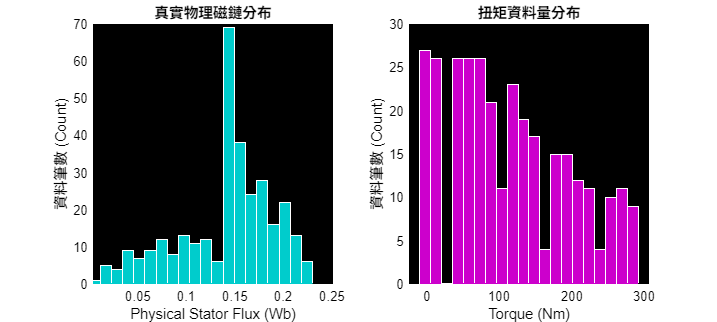


% --- 【修正】將統計結果整理成 App 可讀取的欄位，回存進 processed_bundle.mat ---
% app2.mlapp 的 updateDataDistributionUI() 需要 report / stator_flux / torque 這三個欄位，
% 但先前的版本只有 save() 了 X_raw/Y_raw 等原始數據，並沒有存這三個，
% 導致 App 的「資料分布」分頁永遠讀不到東西。
report.total_count    = total_pts;
report.flux_low_cnt   = low_flux;  report.flux_low_ratio  = (low_flux/total_pts)*100;
report.flux_mid_cnt   = mid_flux;  report.flux_mid_ratio  = (mid_flux/total_pts)*100;
report.flux_high_cnt  = high_flux; report.flux_high_ratio = (high_flux/total_pts)*100;
report.tq_low_cnt     = low_trq;   report.tq_low_ratio    = (low_trq/total_pts)*100;
report.tq_mid_cnt     = mid_trq;   report.tq_mid_ratio    = (mid_trq/total_pts)*100;
report.tq_high_cnt    = high_trq;  report.tq_high_ratio   = (high_trq/total_pts)*100;
report.id_deep_cnt    = fw_pts;    report.id_deep_ratio   = (fw_pts/total_pts)*100;

stator_flux = flux_mag;
torque      = trq;
save('processed_bundle.mat', 'report', 'stator_flux', 'torque', '-append');

f_eda = figure('Name', '訓練數據分布儀表板 (True Physical Wb)', 'Color', 'w', 'Position', [150, 200, 1000, 450]);
subplot(1,2,1); hold on; grid on; box on; set(gca, 'Color', 'k', 'XColor', 'k', 'YColor', 'k');
histogram(flux_mag, 20, 'FaceColor', '#00FFFF', 'EdgeColor', 'w', 'FaceAlpha', 0.8);
title('真實物理磁鏈分布', 'Color', 'k', 'FontWeight', 'bold');
xlabel('Physical Stator Flux (Wb)', 'Color', 'k'); ylabel('資料筆數 (Count)', 'Color', 'k');
xlim([min(flux_mag)*0.9, max(flux_mag)*1.1]);

subplot(1,2,2); hold on; grid on; box on; set(gca, 'Color', 'k', 'XColor', 'k', 'YColor', 'k');
histogram(trq, 20, 'FaceColor', '#FF00FF', 'EdgeColor', 'w', 'FaceAlpha', 0.8);
title('扭矩資料量分布', 'Color', 'k', 'FontWeight', 'bold');
xlabel('Torque (Nm)', 'Color', 'k'); ylabel('資料筆數 (Count)', 'Color', 'k');


%% Step 2: DNN 模型訓練
load('processed_bundle.mat');
p = motor.p; Flux = motor.Flux; Imax = motor.Imax;
fprintf('\n▶ [2/6] Step 2: 啟動雙模型 AI 訓練...\n');


▶ [2/6] Step 2: 啟動雙模型 AI 訓練...



Y_theory_base = Y_theory;

Mech_Power   = X_clean(:,1) .* (X_clean(:,2) .* pi / 30);
wr_rad       = X_clean(:,2) .* (pi/30) .* motor.p;
Back_EMF     = wr_rad .* motor.Flux;

Ld_dyn = motor.Ld_interp(Y_theory_base(:,1), Y_theory_base(:,2));
Lq_dyn = motor.Lq_interp(Y_theory_base(:,1), Y_theory_base(:,2));

V_theory_est = sqrt((motor.Rs.*Y_theory_base(:,1) - wr_rad.*Lq_dyn.*Y_theory_base(:,2)).^2 + ...
    (motor.Rs.*Y_theory_base(:,2) + wr_rad.*(motor.Flux + Ld_dyn.*Y_theory_base(:,1))).^2);

X_features = [X_clean, Y_theory_base, Mech_Power, Back_EMF, V_theory_est];

in_dim     = size(X_features, 2);
numSamples = size(X_features, 1);
out_dim    = size(Y_clean, 2);
rng(1);
[trainIdx, valIdx, ~] = dividerand(numSamples, 0.8, 0.2, 0.0);

Y_mean_res = mean(Y_target_residual, 1); Y_std_res = std(Y_target_residual, 0, 1) + 1e-6;
Y_norm_res = (Y_target_residual - Y_mean_res) ./ Y_std_res;

Y_mean_dir = mean(Y_target_direct, 1);   Y_std_dir = std(Y_target_direct, 0, 1) + 1e-6;
Y_norm_dir = (Y_target_direct - Y_mean_dir) ./ Y_std_dir;

layers_base = [
    featureInputLayer(in_dim, 'Normalization', 'zscore')
    fullyConnectedLayer(64); leakyReluLayer(0.1)
    fullyConnectedLayer(32); leakyReluLayer(0.1)
    fullyConnectedLayer(out_dim); regressionLayer()
    ];

layers_dir = layers_base; layers_res = layers_base;

options_base = trainingOptions('adam', ...
    'MaxEpochs', 1500, 'MiniBatchSize', 1024, 'Shuffle', 'never', ...
    'InitialLearnRate', 0.0025, 'L2Regularization', 1e-4, 'GradientThreshold', 1.0, ...
    'LearnRateSchedule', 'piecewise', 'LearnRateDropPeriod', 500, 'LearnRateDropFactor', 0.5, ...
    'ValidationFrequency', 10, 'ValidationPatience', 200, 'Plots', 'none', ...
    'Verbose', true, 'VerboseFrequency', 100);

options_dir = options_base; options_dir.ValidationData = {X_features(valIdx,:), Y_norm_dir(valIdx,:)};
options_res = options_base; options_res.ValidationData = {X_features(valIdx,:), Y_norm_res(valIdx,:)};
options_res.InitialLearnRate = 0.002;

fprintf('\n--- 正在訓練直接映射模型 ---\n');


--- 正在訓練直接映射模型 ---


[net_direct, info_dir] = trainNetwork(X_features(trainIdx,:), Y_norm_dir(trainIdx,:), layers_dir, options_dir);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |         1.61 |         1.40 |       1.2947 |       0.9780 |          0.0025 |
|      10 |          10 |       00:00:00 |         0.72 |         0.67 |       0.2625 |       0.2236 |          0.0025 |
|      20 |          20 |       00:00:00 |         0.51 |         0.51 |       0.1296 |       0.1280 |          0.0025 |
|      30 |          30 |       00:00:00 |         0.39 |         0.38 |       0.0748 |   


fprintf('\n--- 正在訓練物理殘差模型 ---\n');


--- 正在訓練物理殘差模型 ---


[net_residual, info_res] = trainNetwork(X_features(trainIdx,:), Y_norm_res(trainIdx,:), layers_res, options_res);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |         1.66 |         1.63 |       1.3827 |       1.3316 |          0.0020 |
|      10 |          10 |       00:00:00 |         1.04 |         1.08 |       0.5401 |       0.5785 |          0.0020 |
|      20 |          20 |       00:00:00 |         0.76 |         0.78 |       0.2923 |       0.3043 |          0.0020 |
|      30 |          30 |       00:00:00 |         0.62 |         0.62 |       0.1937 |   

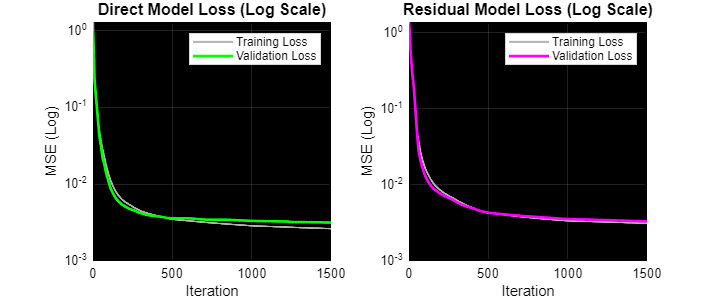


% --- 【修正】把訓練過程的 loss 曲線也存進去，App 的 updateTrainingTrendUI() 需要這 4 個欄位 ---
loss_history_dir     = info_dir.TrainingLoss;
val_loss_history_dir = info_dir.ValidationLoss;
loss_history_res     = info_res.TrainingLoss;
val_loss_history_res = info_res.ValidationLoss;

save('trained_model_dual.mat', 'net_direct', 'net_residual', 'Y_mean_dir', 'Y_std_dir', 'Y_mean_res', 'Y_std_res', 'cfg', ...
    'loss_history_dir', 'val_loss_history_dir', 'loss_history_res', 'val_loss_history_res');

f_trend = figure('Name', 'AI 訓練收斂趨勢圖 (Log Scale)', 'Color', 'w', 'Position', [200, 200, 1200, 500]);
ax_dir = subplot(1,2,1); hold on; grid on; box on;
set(ax_dir, 'Color', 'k', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.5 0.5 0.5], 'YScale', 'log');
plot(1:length(info_dir.TrainingLoss), info_dir.TrainingLoss, 'Color', [0.7 0.7 0.7], 'LineWidth', 1.5, 'DisplayName', 'Training Loss');
plot(find(~isnan(info_dir.ValidationLoss)), info_dir.ValidationLoss(~isnan(info_dir.ValidationLoss)), 'g', 'LineWidth', 2, 'DisplayName', 'Validation Loss');
title(ax_dir, 'Direct Model Loss (Log Scale)', 'Color', 'k', 'FontSize', 12, 'FontWeight', 'bold');
xlabel(ax_dir, 'Iteration', 'Color', 'k'); ylabel(ax_dir, 'MSE (Log)', 'Color', 'k'); legend('show', 'TextColor', 'k', 'Color', 'w');

ax_res = subplot(1,2,2); hold on; grid on; box on;
set(ax_res, 'Color', 'k', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.5 0.5 0.5], 'YScale', 'log');
plot(1:length(info_res.TrainingLoss), info_res.TrainingLoss, 'Color', [0.7 0.7 0.7], 'LineWidth', 1.5, 'DisplayName', 'Training Loss');
plot(find(~isnan(info_res.ValidationLoss)), info_res.ValidationLoss(~isnan(info_res.ValidationLoss)), 'm', 'LineWidth', 2, 'DisplayName', 'Validation Loss');
title(ax_res, 'Residual Model Loss (Log Scale)', 'Color', 'k', 'FontSize', 12, 'FontWeight', 'bold');
xlabel(ax_res, 'Iteration', 'Color', 'k'); ylabel(ax_res, 'MSE (Log)', 'Color', 'k'); legend('show', 'TextColor', 'k', 'Color', 'w');


%% Step 3: 模型預測與量化驗證
load('trained_model_dual.mat'); load('processed_bundle.mat');
p = motor.p; Flux = motor.Flux; Imax = motor.Imax;
fprintf('\n▶ [3/6] Step 3: 啟動 AI 深度預測診斷與誤差分析...\n');


▶ [3/6] Step 3: 啟動 AI 深度預測診斷與誤差分析...


X_sequence      = X_clean;
Y_sequence_real = Y_clean;
numSamples = size(X_sequence, 1);
rng(1); [trainIdx, valIdx, ~] = dividerand(numSamples, 0.8, 0.2, 0.0);

Y_theory_seq = calculate_theoretical_currents(X_sequence(:,1), X_sequence(:,2), motor);

Mech_Power_seq   = X_sequence(:,1) .* (X_sequence(:,2) .* pi / 30);
wr_rad_seq       = X_sequence(:,2) .* (pi/30) .* motor.p;
Back_EMF_seq     = wr_rad_seq .* motor.Flux;

Ld_dyn_seq = motor.Ld_interp(Y_theory_seq(:,1), Y_theory_seq(:,2));
Lq_dyn_seq = motor.Lq_interp(Y_theory_seq(:,1), Y_theory_seq(:,2));
V_theory_est_seq = sqrt((motor.Rs.*Y_theory_seq(:,1) - wr_rad_seq.*Lq_dyn_seq.*Y_theory_seq(:,2)).^2 + ...
    (motor.Rs.*Y_theory_seq(:,2) + wr_rad_seq.*(motor.Flux + Ld_dyn_seq.*Y_theory_seq(:,1))).^2);

X_features_seq = [X_sequence, Y_theory_seq, Mech_Power_seq, Back_EMF_seq, V_theory_est_seq];

Y_pred_dir_raw = predict(net_direct, X_features_seq) .* Y_std_dir + Y_mean_dir;
Y_pred_dir = Y_pred_dir_raw;
Imag_pred_seq = sqrt(Y_pred_dir(:,1).^2 + Y_pred_dir(:,2).^2);
over_dir_idx = Imag_pred_seq > motor.Imax;
if any(over_dir_idx)
    Y_pred_dir(over_dir_idx, 1) = Y_pred_dir(over_dir_idx, 1) .* (motor.Imax ./ Imag_pred_seq(over_dir_idx));
    Y_pred_dir(over_dir_idx, 2) = Y_pred_dir(over_dir_idx, 2) .* (motor.Imax ./ Imag_pred_seq(over_dir_idx));
end

Y_pred_res_raw = predict(net_residual, X_features_seq) .* Y_std_res + Y_mean_res;
Y_pred_res = zeros(size(Y_pred_res_raw));
Y_pred_res(:, 1:2) = Y_theory_seq(:, 1:2) + Y_pred_res_raw(:, 1:2);
I_mag_res_seq = sqrt(Y_pred_res(:,1).^2 + Y_pred_res(:,2).^2);
over_res_idx = I_mag_res_seq > motor.Imax;
if any(over_res_idx)
    Y_pred_res(over_res_idx, 1) = Y_pred_res(over_res_idx, 1) .* (motor.Imax ./ I_mag_res_seq(over_res_idx));
    Y_pred_res(over_res_idx, 2) = Y_pred_res(over_res_idx, 2) .* (motor.Imax ./ I_mag_res_seq(over_res_idx));
end

Y_pred_dir(:,1) = min(Y_pred_dir(:,1), 0); Y_pred_dir(:,2) = max(Y_pred_dir(:,2), 0);
Y_pred_res(:,1) = min(Y_pred_res(:,1), 0); Y_pred_res(:,2) = max(Y_pred_res(:,2), 0);

% --- 【修正】把 True vs Predicted 的散佈圖資料存進去，App 的 4 張散佈圖需要這 3 個欄位 ---
Y_test = Y_sequence_real;
save('trained_model_dual.mat', 'Y_test', 'Y_pred_dir', 'Y_pred_res', '-append');

Y_pred_norm_dir = double(predict(net_direct, X_features_seq));
Y_pred_norm_res = double(predict(net_residual, X_features_seq));
Y_norm_dir_val = double((Y_target_direct - Y_mean_dir) ./ Y_std_dir);
Y_norm_res_val = double((Y_target_residual - Y_mean_res) ./ Y_std_res);

MSE_dir_train = mean((Y_pred_norm_dir(trainIdx, :) - Y_norm_dir_val(trainIdx, :)).^2, 'all');
MSE_dir_val   = mean((Y_pred_norm_dir(valIdx, :) - Y_norm_dir_val(valIdx, :)).^2, 'all');
MSE_res_train = mean((Y_pred_norm_res(trainIdx, :) - Y_norm_res_val(trainIdx, :)).^2, 'all');
MSE_res_val   = mean((Y_pred_norm_res(valIdx, :) - Y_norm_res_val(valIdx, :)).^2, 'all');

fprintf('【直接映射模型】 訓練集 Loss (MSE): %.6f | 驗證集 Loss (MSE): %.6f\n', MSE_dir_train, MSE_dir_val);

【直接映射模型】 訓練集 Loss (MSE): 0.002639 | 驗證集 Loss (MSE): 0.003167


fprintf('【物理殘差模型】 訓練集 Loss (MSE): %.6f | 驗證集 Loss (MSE): %.6f\n', MSE_res_train, MSE_res_val);

【物理殘差模型】 訓練集 Loss (MSE): 0.003134 | 驗證集 Loss (MSE): 0.003315


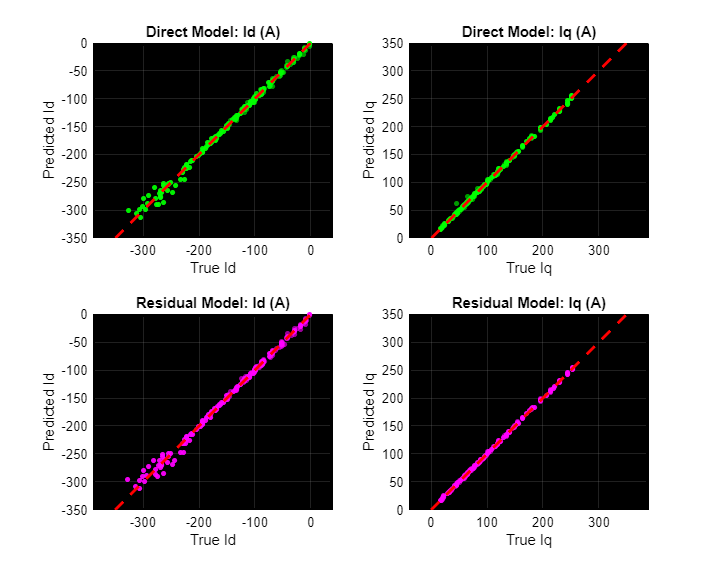


Total_Err_dir = sqrt((Y_pred_dir(:,1) - Y_sequence_real(:,1)).^2 + (Y_pred_dir(:,2) - Y_sequence_real(:,2)).^2);
Total_Err_res = sqrt((Y_pred_res(:,1) - Y_sequence_real(:,1)).^2 + (Y_pred_res(:,2) - Y_sequence_real(:,2)).^2);

f_parity = figure('Name', '診斷 1: 模型預測偏差分析 (Parity Plot)', 'Color', 'w', 'Position', [100, 100, 1000, 800]);
subplot(2,2,1); hold on; grid on; box on; set(gca, 'Color', 'k', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.5 0.5 0.5]); scatter(Y_sequence_real(:,1), Y_pred_dir(:,1), 15, 'g', 'filled', 'MarkerFaceAlpha', 0.6); plot([-Imax, 0], [-Imax, 0], 'r--', 'LineWidth', 2); title('Direct Model: Id (A)', 'Color', 'k'); xlabel('True Id', 'Color', 'k'); ylabel('Predicted Id', 'Color', 'k'); axis equal;
subplot(2,2,2); hold on; grid on; box on; set(gca, 'Color', 'k', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.5 0.5 0.5]); scatter(Y_sequence_real(:,2), Y_pred_dir(:,2), 15, 'g', 'filled', 'MarkerFaceAlpha', 0.6); plot([0, Imax], [0, Imax], 'r--', 'LineWidth', 2); title('Direct Model: Iq (A)', 'Color', 'k'); xlabel('True Iq', 'Color', 'k'); ylabel('Predicted Iq', 'Color', 'k'); axis equal;
subplot(2,2,3); hold on; grid on; box on; set(gca, 'Color', 'k', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.5 0.5 0.5]); scatter(Y_sequence_real(:,1), Y_pred_res(:,1), 15, 'm', 'filled', 'MarkerFaceAlpha', 0.6); plot([-Imax, 0], [-Imax, 0], 'r--', 'LineWidth', 2); title('Residual Model: Id (A)', 'Color', 'k'); xlabel('True Id', 'Color', 'k'); ylabel('Predicted Id', 'Color', 'k'); axis equal;
subplot(2,2,4); hold on; grid on; box on; set(gca, 'Color', 'k', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.5 0.5 0.5]); scatter(Y_sequence_real(:,2), Y_pred_res(:,2), 15, 'm', 'filled', 'MarkerFaceAlpha', 0.6); plot([0, Imax], [0, Imax], 'r--', 'LineWidth', 2); title('Residual Model: Iq (A)', 'Color', 'k'); xlabel('True Iq', 'Color', 'k'); ylabel('Predicted Iq', 'Color', 'k'); axis equal;


%% Step 4: 生成 3D 查表 (AI 生成)
load('trained_model_dual.mat'); load('processed_bundle.mat');
p = motor.p; Flux = motor.Flux; Imax = motor.Imax;
fprintf('\n▶ [4/6] Step 4: 視覺化分析與查表產出...\n');


▶ [4/6] Step 4: 視覺化分析與查表產出...



speed_vec  = 200:50:13500; torque_vec = 0:2:300;
[SpeedGrid, TorqueGrid] = meshgrid(speed_vec, torque_vec);

Y_theory_q = calculate_theoretical_currents(TorqueGrid(:), SpeedGrid(:), motor);
Mech_Power_q   = TorqueGrid(:) .* (SpeedGrid(:) .* pi / 30);
wr_rad_q       = SpeedGrid(:) .* (pi/30) .* motor.p; Back_EMF_q = wr_rad_q .* motor.Flux;
Ld_dyn_q = motor.Ld_interp(Y_theory_q(:,1), Y_theory_q(:,2)); Lq_dyn_q = motor.Lq_interp(Y_theory_q(:,1), Y_theory_q(:,2));
V_theory_est_q = sqrt((motor.Rs.*Y_theory_q(:,1) - wr_rad_q.*Lq_dyn_q.*Y_theory_q(:,2)).^2 + (motor.Rs.*Y_theory_q(:,2) + wr_rad_q.*(motor.Flux + Ld_dyn_q.*Y_theory_q(:,1))).^2);

X_features_q = [TorqueGrid(:), SpeedGrid(:), Y_theory_q, Mech_Power_q, Back_EMF_q, V_theory_est_q];

Y_pred_dir_raw = predict(net_direct, X_features_q) .* Y_std_dir + Y_mean_dir;
Id_dir_raw = double(reshape(Y_pred_dir_raw(:, 1), size(SpeedGrid))); Iq_dir_raw = double(reshape(Y_pred_dir_raw(:, 2), size(SpeedGrid)));
Imag_dir = sqrt(Id_dir_raw.^2 + Iq_dir_raw.^2); over_dir = Imag_dir > motor.Imax;
Id_dir_raw(over_dir) = Id_dir_raw(over_dir) .* (motor.Imax ./ Imag_dir(over_dir)); Iq_dir_raw(over_dir) = Iq_dir_raw(over_dir) .* (motor.Imax ./ Imag_dir(over_dir));

Y_pred_res_raw = predict(net_residual, X_features_q) .* Y_std_res + Y_mean_res;
Id_res_raw = double(reshape(Y_theory_q(:, 1) + Y_pred_res_raw(:, 1), size(SpeedGrid))); Iq_res_raw = double(reshape(Y_theory_q(:, 2) + Y_pred_res_raw(:, 2), size(SpeedGrid)));
Imag_res = sqrt(Id_res_raw.^2 + Iq_res_raw.^2); over_res = Imag_res > motor.Imax;
Id_res_raw(over_res) = Id_res_raw(over_res) .* (motor.Imax ./ Imag_res(over_res)); Iq_res_raw(over_res) = Iq_res_raw(over_res) .* (motor.Imax ./ Imag_res(over_res));

Id_dir_raw = imgaussfilt(Id_dir_raw, 0.8); Iq_dir_raw = imgaussfilt(Iq_dir_raw, 0.8);
Id_res_raw = imgaussfilt(Id_res_raw, 0.8); Iq_res_raw = imgaussfilt(Iq_res_raw, 0.8);

Id_Table_Final = Id_dir_raw; Iq_Table_Final = Iq_dir_raw; Id_Table_Final(Id_Table_Final > 0) = 0; Iq_Table_Final(Iq_Table_Final < 0) = 0;
Id_Table_Res_Final = Id_res_raw; Iq_Table_Res_Final = Iq_res_raw; Id_Table_Res_Final(Id_Table_Res_Final > 0) = 0; Iq_Table_Res_Final(Iq_Table_Res_Final < 0) = 0;

F_mask = scatteredInterpolant(double(X_clean(:,2)), double(X_clean(:,1)), ones(size(X_clean(:,1))), 'nearest', 'none');

valid_footprint = ~isnan(F_mask(SpeedGrid, TorqueGrid));
S_bnd = double(X_clean(:,2)); T_bnd = double(X_clean(:,1)); bnd_idx = boundary(S_bnd, T_bnd, 0.5);
in_hull_2d = inpolygon(SpeedGrid, TorqueGrid, S_bnd(bnd_idx), T_bnd(bnd_idx));

decimation_mask = false(size(Id_dir_raw)); decimation_mask(:, 1:4:end) = true;
Id_Plot_dir = Id_dir_raw; Iq_Plot_dir = Iq_dir_raw; Id_Plot_res = Id_res_raw; Iq_Plot_res = Iq_res_raw;
mag_plot_dir = sqrt(Id_Plot_dir.^2 + Iq_Plot_dir.^2);
Id_Plot_dir(mag_plot_dir > motor.Imax * 1.01) = NaN; Iq_Plot_dir(mag_plot_dir > motor.Imax * 1.01) = NaN;
mag_plot_res = sqrt(Id_Plot_res.^2 + Iq_Plot_res.^2);
Id_Plot_res(mag_plot_res > motor.Imax * 1.01) = NaN; Iq_Plot_res(mag_plot_res > motor.Imax * 1.01) = NaN;
Id_Plot_dir(~in_hull_2d | ~decimation_mask) = NaN; Iq_Plot_dir(~in_hull_2d | ~decimation_mask) = NaN;
Id_Plot_res(~in_hull_2d | ~decimation_mask) = NaN; Iq_Plot_res(~in_hull_2d | ~decimation_mask) = NaN;

[~, spd_idx] = min(abs(speed_vec - 1000));
iq_mtpa_dir = Iq_Table_Final(:, spd_idx); id_mtpa_dir = Id_Table_Final(:, spd_idx);
val_dir = iq_mtpa_dir > 5 & sqrt(id_mtpa_dir.^2 + iq_mtpa_dir.^2) < motor.Imax * 0.99;
if sum(val_dir) > 2, c_dir = [iq_mtpa_dir(val_dir).^2, iq_mtpa_dir(val_dir)] \ id_mtpa_dir(val_dir); iq_min_dir = min(iq_mtpa_dir(val_dir)); iq_max_dir = min(max(iq_mtpa_dir(val_dir)), motor.Imax); iq_line_dir = linspace(iq_min_dir, iq_max_dir, 100)'; id_line_dir = c_dir(1)*iq_line_dir.^2 + c_dir(2)*iq_line_dir; else, iq_line_dir = NaN; id_line_dir = NaN; end
iq_mtpa_res = Iq_Table_Res_Final(:, spd_idx); id_mtpa_res = Id_Table_Res_Final(:, spd_idx);
val_res = iq_mtpa_res > 5 & sqrt(id_mtpa_res.^2 + iq_mtpa_res.^2) < motor.Imax * 0.99;
if sum(val_res) > 2, c_res = [iq_mtpa_res(val_res).^2, iq_mtpa_res(val_res)] \ id_mtpa_res(val_res); iq_min_res = min(iq_mtpa_res(val_res)); iq_max_res = min(max(iq_mtpa_res(val_res)), motor.Imax); iq_line_res = linspace(iq_min_res, iq_max_res, 100)'; id_line_res = c_res(1)*iq_line_res.^2 + c_res(2)*iq_line_res; else, iq_line_res = NaN; id_line_res = NaN; end

[id_bg, iq_bg] = meshgrid(-I_plot_limit:5:50, 0:5:I_plot_limit); Ld_bg = motor.Ld_interp(id_bg, iq_bg); Lq_bg = motor.Lq_interp(id_bg, iq_bg); T_bg = 1.5 * p * (Flux .* iq_bg + (Ld_bg - Lq_bg) .* id_bg .* iq_bg); theta = linspace(pi/2, pi, 200); trq_levels = [50 100 150 200 250 290];

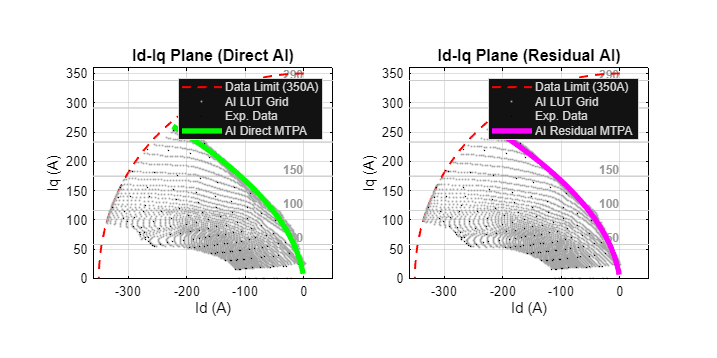


f_iq_ai = figure('Name', 'ID-IQ Plane 分析 (AI)', 'Color', 'w', 'Position', [50, 100, 1200, 600]);
ax1 = subplot(1,2,1); set(ax1, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.5 0.5 0.5]); hold on; grid on; box on; contour(ax1, id_bg, iq_bg, T_bg, trq_levels, 'LineColor', [0.8 0.8 0.8], 'HandleVisibility', 'off'); for lvl = trq_levels, iq_lvl = lvl / (1.5 * p * (Flux + (motor.Ld - motor.Lq) * (-2))); text(ax1, -2, iq_lvl, sprintf('%d', lvl), 'Color', [0.6 0.6 0.6], 'FontSize', 9, 'FontWeight', 'bold', 'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom'); end
plot(ax1, motor.Imax*cos(theta), motor.Imax*sin(theta), 'r--', 'LineWidth', 1.5, 'DisplayName', sprintf('Data Limit (%dA)', motor.Imax)); plot(ax1, Id_Plot_dir(:), Iq_Plot_dir(:), '.', 'Color', [0.65 0.65 0.65], 'MarkerSize', 4, 'DisplayName', 'AI LUT Grid'); plot(ax1, Y_raw(:,1), Y_raw(:,2), 'k.', 'MarkerSize', 2, 'DisplayName', 'Exp. Data'); plot(ax1, id_line_dir, iq_line_dir, 'g-', 'LineWidth', 4, 'DisplayName', 'AI Direct MTPA'); title(ax1, 'Id-Iq Plane (Direct AI)', 'Color', 'k', 'FontSize', 12, 'FontWeight', 'bold'); xlabel(ax1, 'Id (A)', 'Color', 'k'); ylabel(ax1, 'Iq (A)', 'Color', 'k'); xlim([-I_plot_limit 50]); ylim([0 I_plot_limit]); axis equal; legend('Location', 'northeast');
ax2 = subplot(1,2,2); set(ax2, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.5 0.5 0.5]); hold on; grid on; box on; contour(ax2, id_bg, iq_bg, T_bg, trq_levels, 'LineColor', [0.8 0.8 0.8], 'HandleVisibility', 'off'); for lvl = trq_levels, iq_lvl = lvl / (1.5 * p * (Flux + (motor.Ld - motor.Lq) * (-2))); text(ax2, -2, iq_lvl, sprintf('%d', lvl), 'Color', [0.6 0.6 0.6], 'FontSize', 9, 'FontWeight', 'bold', 'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom'); end
plot(ax2, motor.Imax*cos(theta), motor.Imax*sin(theta), 'r--', 'LineWidth', 1.5, 'DisplayName', sprintf('Data Limit (%dA)', motor.Imax)); plot(ax2, Id_Plot_res(:), Iq_Plot_res(:), '.', 'Color', [0.65 0.65 0.65], 'MarkerSize', 4, 'DisplayName', 'AI LUT Grid'); plot(ax2, Y_raw(:,1), Y_raw(:,2), 'k.', 'MarkerSize', 2, 'DisplayName', 'Exp. Data'); plot(ax2, id_line_res, iq_line_res, 'm-', 'LineWidth', 4, 'DisplayName', 'AI Residual MTPA'); title(ax2, 'Id-Iq Plane (Residual AI)', 'Color', 'k', 'FontSize', 12, 'FontWeight', 'bold'); xlabel(ax2, 'Id (A)', 'Color', 'k'); ylabel(ax2, 'Iq (A)', 'Color', 'k'); xlim([-I_plot_limit 50]); ylim([0 I_plot_limit]); axis equal; legend('Location', 'northeast');


% =========================================================================
% ===== 【徹底修復】：1D 行級單調轉換 (消除 3D Triangulation 所有破圖) =====
Ld_cl = motor.Ld_interp(Y_clean(:,1), Y_clean(:,2)); Lq_cl = motor.Lq_interp(Y_clean(:,1), Y_clean(:,2));
Flux_clean = sqrt((motor.Flux + Ld_cl.*Y_clean(:,1)).^2 + (Lq_cl.*Y_clean(:,2)).^2);
flux_min_val = min(Flux_clean); flux_max_val = max(Flux_clean); % 貼合真實 Wb 範圍

flux_vec = linspace(flux_min_val * 0.9, flux_max_val * 1.05, 50);
[FluxGrid_Uniform, TorqueGrid_Uniform] = meshgrid(flux_vec, torque_vec);

% 呼叫最新研發的 1D 行級重鑄函式
[Id_Flux_AI, Iq_Flux_AI] = resample_LUT_to_flux(SpeedGrid, TorqueGrid, Id_Table_Res_Final, Iq_Table_Res_Final, flux_vec, torque_vec, motor);

F_mask_flux = scatteredInterpolant(Flux_clean, X_clean(:,1), ones(size(Flux_clean)), 'nearest', 'none');

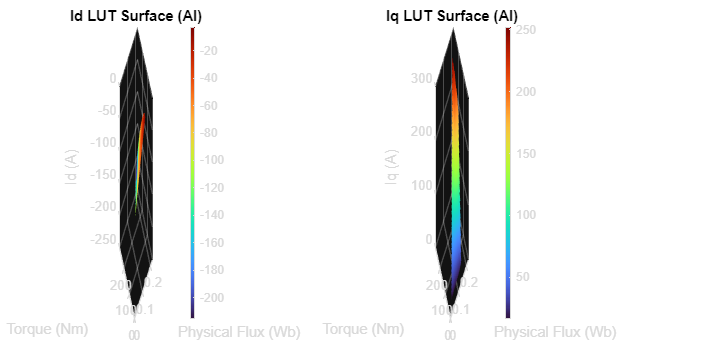

valid_footprint_flux = ~isnan(F_mask_flux(FluxGrid_Uniform, TorqueGrid_Uniform));

Id_Surf_Plot_AI = Id_Flux_AI; Id_Surf_Plot_AI(~valid_footprint_flux) = NaN;
Iq_Surf_Plot_AI = Iq_Flux_AI; Iq_Surf_Plot_AI(~valid_footprint_flux) = NaN;

f_3d_ai = figure('Name', '3D LUT 曲面 (AI - Flux Axis)', 'Color', 'w', 'Position', [150, 150, 1000, 500]); az = -40; el = 30;
ax3d_id = subplot(1,2,1); surf(FluxGrid_Uniform, TorqueGrid_Uniform, Id_Surf_Plot_AI, 'EdgeColor', 'none'); colormap turbo; colorbar; view([az, el]);
title(ax3d_id, 'Id LUT Surface (AI)', 'Color', 'k', 'FontWeight', 'bold'); xlabel('Physical Flux (Wb)'); ylabel('Torque (Nm)'); zlabel('Id (A)');
ax3d_iq = subplot(1,2,2); surf(FluxGrid_Uniform, TorqueGrid_Uniform, Iq_Surf_Plot_AI, 'EdgeColor', 'none'); colormap turbo; colorbar; view([az, el]);
title(ax3d_iq, 'Iq LUT Surface (AI)', 'Color', 'k', 'FontWeight', 'bold'); xlabel('Physical Flux (Wb)'); ylabel('Torque (Nm)'); zlabel('Iq (A)');


excel_filename = 'AI_Generated_LUT_NewMotor.xlsx';
try
    if isfile(excel_filename), delete(excel_filename); end
    writematrix([NaN, flux_vec; torque_vec', Id_Surf_Plot_AI], excel_filename, 'Sheet', 'Id_Table');
    writematrix([NaN, flux_vec; torque_vec', Iq_Surf_Plot_AI], excel_filename, 'Sheet', 'Iq_Table');
    fprintf('  AI Flux 查表已成功匯出至: %s\n', excel_filename);
catch ME
    fprintf(2, '\n Excel 匯出失敗。錯誤: %s\n', ME.message);
end

  AI Flux 查表已成功匯出至: AI_Generated_LUT_NewMotor.xlsx



%% Step 5: 真實數據工程化修整、還原與分析
fprintf('\n▶ [5/6] Step 5: 正在進行真實數據處理 ...\n');


▶ [5/6] Step 5: 正在進行真實數據處理 ...



% 補回遺失的變數宣告 (非常重要！)
trq_clean = X_clean(:, 1);
spd_clean = X_clean(:, 2);
id_clean  = Y_clean(:, 1);
iq_clean  = Y_clean(:, 2);

F_id = scatteredInterpolant(X_clean(:,2), X_clean(:,1), Y_clean(:,1), 'natural', 'none');

F_iq = scatteredInterpolant(X_clean(:,2), X_clean(:,1), Y_clean(:,2), 'natural', 'none');

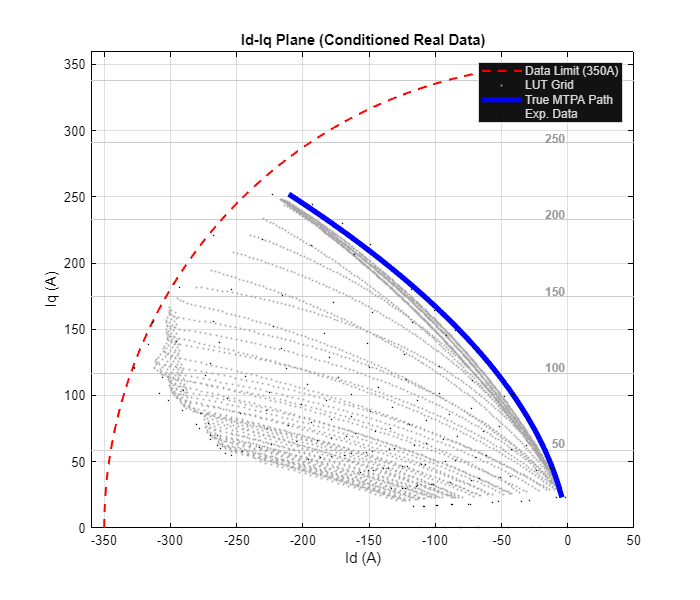

Id_Table_Real = F_id(SpeedGrid, TorqueGrid); Iq_Table_Real = F_iq(SpeedGrid, TorqueGrid);

Ld_idle_val = motor.Ld_interp(0, 0);
for c = 1:size(SpeedGrid, 2)
    wr = SpeedGrid(1, c) * (pi/30) * p;
    if (wr * motor.Flux) <= motor.V_limit, Id_Table_Real(1, c) = 0; else, Id_Table_Real(1, c) = max((motor.V_limit/wr - motor.Flux) / Ld_idle_val, -motor.Imax); end
    Iq_Table_Real(1, c) = 0;
end

Id_Table_Real = medfilt2(Id_Table_Real, [3 3]); Iq_Table_Real = medfilt2(Iq_Table_Real, [3 3]);
Id_Table_Real = imgaussfilt(Id_Table_Real, 1.5); Iq_Table_Real = imgaussfilt(Iq_Table_Real, 1.5);

idx_mtpa_real = spd_clean <= 3000; trq_mtpa_real = trq_clean(idx_mtpa_real); id_mtpa_real_data = id_clean(idx_mtpa_real); iq_mtpa_real_data = iq_clean(idx_mtpa_real);
trq_bins = linspace(min(trq_mtpa_real), max(trq_mtpa_real), 30); id_mtpa_pts = []; iq_mtpa_pts = [];
for b = 1:length(trq_bins)-1
    in_bin = trq_mtpa_real >= trq_bins(b) & trq_mtpa_real <= trq_bins(b+1);
    if sum(in_bin) > 0
        id_b = id_mtpa_real_data(in_bin); iq_b = iq_mtpa_real_data(in_bin);
        [~, min_i] = min(sqrt(id_b.^2 + iq_b.^2)); id_mtpa_pts = [id_mtpa_pts; id_b(min_i)]; iq_mtpa_pts = [iq_mtpa_pts; iq_b(min_i)];
    end
end
val_real = iq_mtpa_pts > 5;
if sum(val_real) > 2, c_real = [iq_mtpa_pts(val_real).^2, iq_mtpa_pts(val_real)] \ id_mtpa_pts(val_real); iq_min_real = min(iq_mtpa_pts(val_real)); iq_max_real = min(max(iq_mtpa_pts(val_real)), motor.Imax); iq_line_real = linspace(iq_min_real, iq_max_real, 100)'; id_line_real = c_real(1)*iq_line_real.^2 + c_real(2)*iq_line_real; else, iq_line_real = NaN; id_line_real = NaN; end

Id_Plot_Real = Id_Table_Real; Iq_Plot_Real = Iq_Table_Real;
I_mag_plot_real = sqrt(Id_Plot_Real.^2 + Iq_Plot_Real.^2);
Id_Plot_Real(I_mag_plot_real > Imax * 1.01) = NaN; Iq_Plot_Real(I_mag_plot_real > Imax * 1.01) = NaN;
Id_Plot_Real(~in_hull_2d | ~decimation_mask) = NaN; Iq_Plot_Real(~in_hull_2d | ~decimation_mask) = NaN;

f_raw_iq = figure('Name', 'ID-IQ Plane 分析 (Real Data)', 'Color', 'w', 'Position', [150, 150, 700, 600]);
ax3 = axes(f_raw_iq); hold on; grid on; box on; set(ax3, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.5 0.5 0.5]); contour(ax3, id_bg, iq_bg, T_bg, trq_levels, 'LineColor', [0.8 0.8 0.8], 'HandleVisibility', 'off');
for lvl = trq_levels, iq_lvl = lvl / (1.5 * p * (motor.Flux + (motor.Ld - motor.Lq) * (-2))); text(ax3, -2, iq_lvl, sprintf('%d', lvl), 'Color', [0.6 0.6 0.6], 'FontSize', 9, 'FontWeight', 'bold', 'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom'); end
plot(ax3, motor.Imax*cos(theta), motor.Imax*sin(theta), 'r--', 'LineWidth', 1.5, 'DisplayName', sprintf('Data Limit (%dA)', motor.Imax)); plot(ax3, Id_Plot_Real(:), Iq_Plot_Real(:), '.', 'Color', [0.65 0.65 0.65], 'MarkerSize', 4, 'DisplayName', 'LUT Grid'); plot(ax3, id_line_real, iq_line_real, 'b-', 'LineWidth', 4, 'DisplayName', 'True MTPA Path'); plot(ax3, Y_raw(:,1), Y_raw(:,2), 'k.', 'MarkerSize', 2, 'DisplayName', 'Exp. Data'); title(ax3, 'Id-Iq Plane (Conditioned Real Data)', 'Color', 'k', 'FontWeight', 'bold'); xlabel('Id (A)'); ylabel('Iq (A)'); xlim([-I_plot_limit 50]); ylim([0 I_plot_limit]); axis equal; legend('Location', 'northeast');

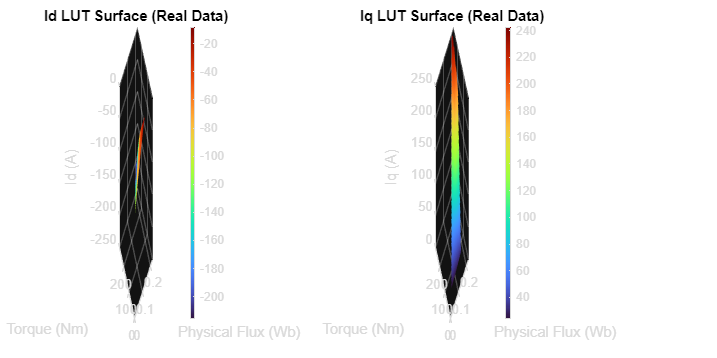


% 真實數據同步套用 1D 行級重鑄
[Id_Flux_Real, Iq_Flux_Real] = resample_LUT_to_flux(SpeedGrid, TorqueGrid, Id_Table_Real, Iq_Table_Real, flux_vec, torque_vec, motor);
Id_Surf_Plot_Real = Id_Flux_Real; Id_Surf_Plot_Real(~valid_footprint_flux) = NaN;
Iq_Surf_Plot_Real = Iq_Flux_Real; Iq_Surf_Plot_Real(~valid_footprint_flux) = NaN;

f_raw_3d = figure('Name', '3D LUT 曲面 (Real Data - Flux Axis)', 'Color', 'w', 'Position', [150, 150, 1000, 500]); az = -40; el = 30;
ax3d_idr = subplot(1,2,1); surf(FluxGrid_Uniform, TorqueGrid_Uniform, Id_Surf_Plot_Real, 'EdgeColor', 'none'); colormap turbo; colorbar; view([az, el]); title(ax3d_idr, 'Id LUT Surface (Real Data)', 'Color', 'k', 'FontWeight', 'bold'); xlabel('Physical Flux (Wb)'); ylabel('Torque (Nm)'); zlabel('Id (A)');
ax3d_iqr = subplot(1,2,2); surf(FluxGrid_Uniform, TorqueGrid_Uniform, Iq_Surf_Plot_Real, 'EdgeColor', 'none'); colormap turbo; colorbar; view([az, el]); title(ax3d_iqr, 'Iq LUT Surface (Real Data)', 'Color', 'k', 'FontWeight', 'bold'); xlabel('Physical Flux (Wb)'); ylabel('Torque (Nm)'); zlabel('Iq (A)');


fprintf('\n  正在匯出修整後的真實數據查表...\n');


  正在匯出修整後的真實數據查表...


excel_filename_raw = 'Raw_Data_LUT_NewMotor.xlsx';
try
    if isfile(excel_filename_raw), delete(excel_filename_raw); end
    writematrix([NaN, flux_vec; torque_vec', Id_Surf_Plot_Real], excel_filename_raw, 'Sheet', 'Id_Table');
    writematrix([NaN, flux_vec; torque_vec', Iq_Surf_Plot_Real], excel_filename_raw, 'Sheet', 'Iq_Table');
    fprintf(' 真實數據查表已成功匯出至: %s\n', excel_filename_raw);
catch ME
    fprintf(2, '\nExcel 匯出失敗！錯誤: %s\n', ME.message);
end

 真實數據查表已成功匯出至: Raw_Data_LUT_NewMotor.xlsx


fprintf('\n▶ Live Script 模塊執行完畢！\n');


▶ Live Script 模塊執行完畢！



%% 附屬函式區塊：理論電流計算求解器
function Y_theory = calculate_theoretical_currents(Torque, Speed, motor)
p = motor.p; Rs = motor.Rs; Flux = motor.Flux; Imax = motor.Imax; V_limit = motor.V_limit * 0.95;
Y_theory = zeros(length(Torque), 2);
Iq_srch = linspace(0, Imax, 500); Id_srch = linspace(0, -Imax, 500); [ID_grid, IQ_grid] = ndgrid(Id_srch, Iq_srch);
LD_grid = motor.Ld_interp(ID_grid, IQ_grid); LQ_grid = motor.Lq_interp(ID_grid, IQ_grid);
T_grid = 1.5 * p * (Flux .* IQ_grid + (LD_grid - LQ_grid) .* ID_grid .* IQ_grid); I_mag_grid = sqrt(ID_grid.^2 + IQ_grid.^2); valid_grid = I_mag_grid <= Imax;
T_req_vec = linspace(0, max(T_grid(valid_grid)), 500); Id_mtpa_vec = zeros(size(T_req_vec)); Iq_mtpa_vec = zeros(size(T_req_vec));
for k = 1:length(T_req_vec)
    mask = valid_grid & (T_grid >= T_req_vec(k)*0.98) & (T_grid <= T_req_vec(k)*1.02); if ~any(mask(:)), mask = valid_grid & (T_grid >= T_req_vec(k)*0.92); end
    if any(mask(:)), [~, min_idx] = min(I_mag_grid(mask)); idx_list = find(mask); Id_mtpa_vec(k) = ID_grid(idx_list(min_idx)); Iq_mtpa_vec(k) = IQ_grid(idx_list(min_idx)); end
end
Id_mtpa_vec = smoothdata(Id_mtpa_vec, 'movmean', 20); Iq_mtpa_vec = smoothdata(Iq_mtpa_vec, 'movmean', 20); T_mtpa_vec = T_req_vec;
opts = optimoptions('fsolve', 'Display', 'none', 'Algorithm', 'trust-region-dogleg');
for i = 1:length(Torque)
    T_req = abs(Torque(i)); wr = Speed(i) * (pi/30) * p;
    if T_req <= 0.5
        if (wr * Flux) <= motor.V_limit, Y_theory(i, :) = [0, 0]; else, Ld_idle = motor.Ld_interp(0, 0); Y_theory(i, :) = [max((motor.V_limit/wr - Flux) / Ld_idle, -Imax), 0]; end; continue;
    end
    if T_req <= max(T_mtpa_vec), Id_target = interp1(T_mtpa_vec, Id_mtpa_vec, T_req, 'linear'); Iq_target = interp1(T_mtpa_vec, Iq_mtpa_vec, T_req, 'linear'); else, Id_target = Id_mtpa_vec(end); Iq_target = Iq_mtpa_vec(end); end
    Ld_mtpa = motor.Ld_interp(Id_target, Iq_target); Lq_mtpa = motor.Lq_interp(Id_target, Iq_target);
    V_mtpa = sqrt((Rs*Id_target - wr*Lq_mtpa*Iq_target)^2 + (Rs*Iq_target + wr*(Flux + Ld_mtpa*Id_target))^2);
    if V_mtpa <= V_limit, Y_theory(i, :) = [Id_target, Iq_target];
    else
        fw_equations = @(x) [1.5 * p * (Flux * x(2) + (motor.Ld_interp(x(1), x(2)) - motor.Lq_interp(x(1), x(2))) * x(1) * x(2)) - T_req; max(0, sqrt((Rs*x(1) - wr*motor.Lq_interp(x(1), x(2))*x(2))^2 + (Rs*x(2) + wr*(Flux + motor.Ld_interp(x(1), x(2))*x(1)))^2) - V_limit)];
        Ld_guess_0 = motor.Ld_interp(Id_target, 0); Id_guess = max(-Imax, min(Id_target, (V_limit/wr - Flux) / Ld_guess_0)); x0 = [Id_guess, Iq_target];
        [sol, ~, exitflag] = fsolve(fw_equations, x0, opts);
        if exitflag > 0 && norm(sol) <= Imax * 1.05, Y_theory(i, :) = [sol(1), sol(2)];
        else
            Id_search = linspace(-Imax, 0, 200); best_Id = x0(1); best_Iq = 0; min_err = inf; fb_Id = x0(1); fb_Iq = 0; min_v_err = inf;
            for k = 1:length(Id_search)
                Ld_tmp = motor.Ld_interp(Id_search(k), Iq_target); Lq_tmp = motor.Lq_interp(Id_search(k), Iq_target); denom = 1.5 * p * (Flux + (Ld_tmp - Lq_tmp) * Id_search(k)); if denom <= 0, continue; end; Iq_cand = T_req / denom;
                if sqrt(Id_search(k)^2 + Iq_cand^2) > Imax * 1.02, continue; end
                Ld_k = motor.Ld_interp(Id_search(k), Iq_cand); Lq_k = motor.Lq_interp(Id_search(k), Iq_cand); V_tmp = sqrt((Rs*Id_search(k) - wr*Lq_k*Iq_cand)^2 + (Rs*Iq_cand + wr*(Flux + Ld_k*Id_search(k)))^2);
                if V_tmp <= V_limit * 1.05, err = abs(T_req - (1.5 * p * (Flux * Iq_cand + (Ld_k - Lq_k) * Id_search(k) * Iq_cand))); if err < min_err, min_err = err; best_Id = Id_search(k); best_Iq = Iq_cand; end
                else, v_err = V_tmp - V_limit; if v_err < min_v_err, min_v_err = v_err; fb_Id = Id_search(k); fb_Iq = Iq_cand; end; end
            end
            if min_err == inf, Y_theory(i, :) = [fb_Id, fb_Iq]; else, Y_theory(i, :) = [best_Id, best_Iq]; end
        end
    end
end
end

%% 輔助函式：全新【1D 嚴格單調映射法】(徹底消滅 3D Triangulation 所有破圖)
function [Id_Out, Iq_Out] = resample_LUT_to_flux(~, ~, Id_Table, Iq_Table, flux_vec, torque_vec, motor)
Id_Out = NaN(length(torque_vec), length(flux_vec));
Iq_Out = NaN(length(torque_vec), length(flux_vec));

% 針對每一條「恆扭矩線」(row-by-row) 進行一維嚴格單調映射
for i = 1:length(torque_vec)
    id_row = Id_Table(i, :);
    iq_row = Iq_Table(i, :);

    % 計算此扭矩線上，各轉速點對應的真實定子磁鏈
    Ld_row = motor.Ld_interp(id_row, iq_row);
    Lq_row = motor.Lq_interp(id_row, iq_row);
    flux_row = sqrt((motor.Flux + Ld_row.*id_row).^2 + (Lq_row.*iq_row).^2);

    % 過濾異常值
    valid = isfinite(flux_row) & isfinite(id_row) & isfinite(iq_row);
    if sum(valid) < 2
        continue;
    end
    f_v = flux_row(valid);
    id_v = id_row(valid);
    iq_v = iq_row(valid);

    % 關鍵算法：強制物理單調性 (轉速升高 -> 磁鏈必須嚴格遞減)
    % 我們只收錄「實質下降」的資料點，直接剔除所有 AI 雜訊造成的反折與垂直重疊
    f_mono = zeros(size(f_v));
    id_mono = zeros(size(id_v));
    iq_mono = zeros(size(iq_v));

    f_mono(1) = f_v(1);
    id_mono(1) = id_v(1);
    iq_mono(1) = iq_v(1);
    cnt = 1;

    for j = 2:length(f_v)
        % 確保磁鏈有確實下降才收錄 (過濾掉 MTPA 區段的重疊點與震盪)
        if f_v(j) < f_mono(cnt) - 1e-4
            cnt = cnt + 1;
            f_mono(cnt) = f_v(j);
            id_mono(cnt) = id_v(j);
            iq_mono(cnt) = iq_v(j);
        end
    end

    if cnt < 2
        Id_Out(i, :) = id_v(1);
        Iq_Out(i, :) = iq_v(1);
        continue;
    end

    % 截取嚴格單調的乾淨陣列
    f_clean  = f_mono(1:cnt);
    id_clean = id_mono(1:cnt);
    iq_clean = iq_mono(1:cnt);

    % 反轉陣列，讓磁鏈變成由小到大 (符合 interp1 要求)
    f_asc  = flip(f_clean);
    id_asc = flip(id_clean);
    iq_asc = flip(iq_clean);

    % 進行 1D 插值映射至指定的整齊 flux_vec 網格上
    id_interp = interp1(f_asc, id_asc, flux_vec, 'linear', 'extrap');
    iq_interp = interp1(f_asc, iq_asc, flux_vec, 'linear', 'extrap');

    % 防呆鎖定：限制查表外插不可超過物理極限 (如 MTPA 上限)
    max_phys = max(f_asc);
    id_interp(flux_vec >= max_phys) = id_asc(end);
    iq_interp(flux_vec >= max_phys) = iq_asc(end);

    min_phys = min(f_asc);
    id_interp(flux_vec <= min_phys) = id_asc(1);
    iq_interp(flux_vec <= min_phys) = iq_asc(1);

    Id_Out(i, :) = id_interp;
    Iq_Out(i, :) = iq_interp;
end

% 套用輕微的 2D 高斯濾波，熨平扭矩線之間的微小過渡，確保 100% 絲滑
Id_Out = imgaussfilt(Id_Out, 1.0);
Iq_Out = imgaussfilt(Iq_Out, 1.0);

% 安全防護：Id 恆為負/零，Iq 恆為正/零
Id_Out(Id_Out > 0) = 0;
Iq_Out(Iq_Out < 0) = 0;
end
